# Example: Plot Field Parameters

Information about the wave-physics of multi-layered structures can be gained by plotting the displacement and stress fields at different points. In `ElasticMatrix`, the angle, frequency and x-z range and over which to plot the displacement or stress fields must be specified. The `.calculateField` method uses the x-z ranges to define a grid, calculates the displacement and stress for each point on the grid for a plane wave at the specified angle and frequency and returns it as a structure. The values of the structure can be plotted independently or given as an argument to the .plotField method. An example is given here, currently the first layer cannot be a vacuum or air.

## Initialize ElasticMatrix Class

Initialize the ElasticMatix object, in this example it will be an aluminium plate in water.

% Medium class:
medium = Medium(...
    'water',Inf, 'aluminium',0.001, 'water',Inf);

% Initialize ElasticMatrix class:
model = ElasticMatrix(medium);

## Setting Parameters

The model can be run over a single pair or vector of angles and frequencies. Ensure that the angle-frequency pair you wish to plot are included within the calculations.

% Chosen angle and frequency:
plot_angle = 19.99; 
plot_frequency = 4.425e6;

% Calculate the angle and frequency:
model.setFrequency(plot_frequency);
model.setAngle(plot_angle);

% Run model:
model.calculate;

... calculating matrix method ... 
... frequency-angle calculation ...
... done ... 


## Define Z and X Vectors for the Plotting Mesh

In this example the aluminium plate is 1 mm thick, and the plotting ranges will be set to be greater than this. The number of points in the plotting range vectors defines the plotting grid density. The Z vector defines the plotting range across the thickness of each layer, and the X vector is parallel to the interface of each layer. 

% Define plotting vectors:
sample_points = 128;
Z = linspace( -1.5e-3, 0.5e-3, sample_points);
X = linspace( -1.5e-3, 1.5e-3, sample_points);

% Calculate the displacement and stress fields:
[output_field] = model.calculateField( ...
    plot_frequency, plot_angle, {Z, X});

... calculating displacement and stress fields ...


## output_field Structure

`output_field` is a structure that contains:

- z - normal displacement field 

- x - transverse displacement field 

- sigma_zz - normal stress field 

- sigma_xz - shear stress field 

- vector of x-range 

- vector of z-range

disp( output_field );

          z_vector: [1×128 double]
          x_vector: [1×128 double]
    x_displacement: [128×128 double]
    z_displacement: [128×128 double]
          sigma_zz: [128×128 double]
          sigma_xz: [128×128 double]



## Plotting the Field Parameters

The field can be plotted by passing the output_field structure to the plot field function. Plot styles: - 'displacement1D' - 'displacement2D' - 'stress1D' - 'stress2D' - 'vector' - 'mesh' - 'surf' - 'all'

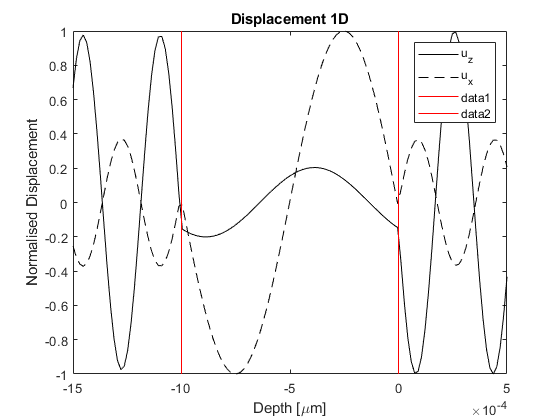

% To plot the normal and transverse displacement along the line x=0 z=Z_hf:
[fig_hand] = model.plotField(output_field, 'displacement1D');

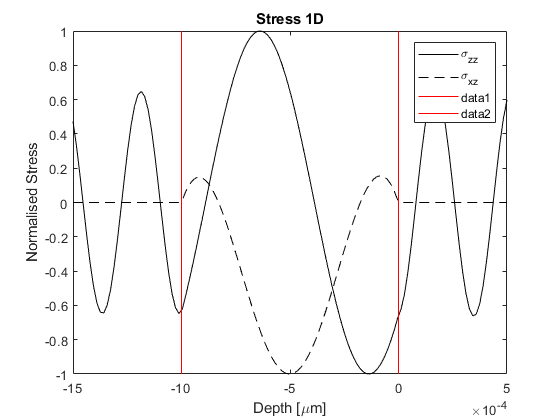


% To plot the normal and transverse displacement along the line x=0 z=Z_hf:
[fig_hand] = model.plotField(output_field, 'stress1D');

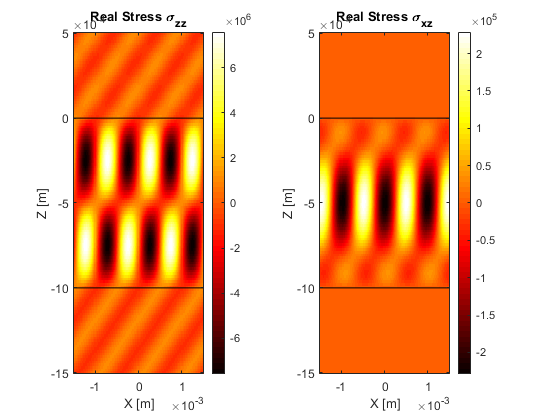

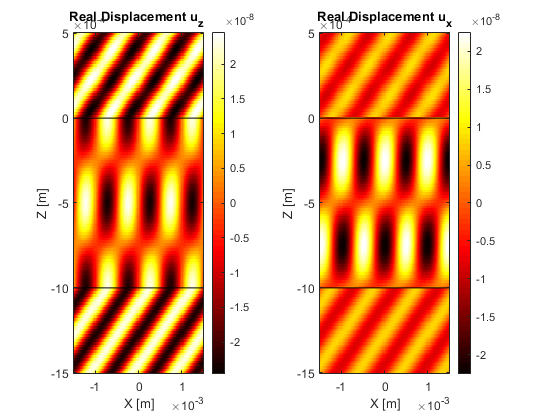


% To plot the 2D fields for displacement and stress:
[fig_hand] = model.plotField(output_field, 'displacement2D', 'stress2D');

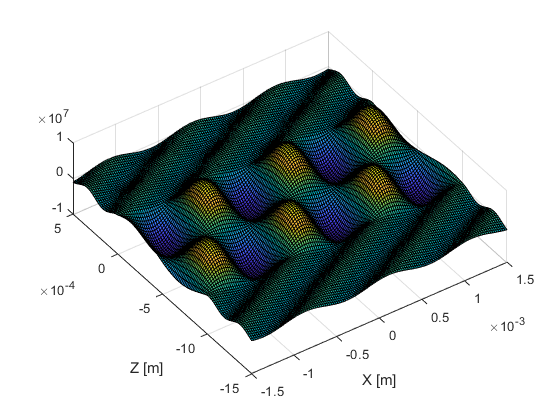

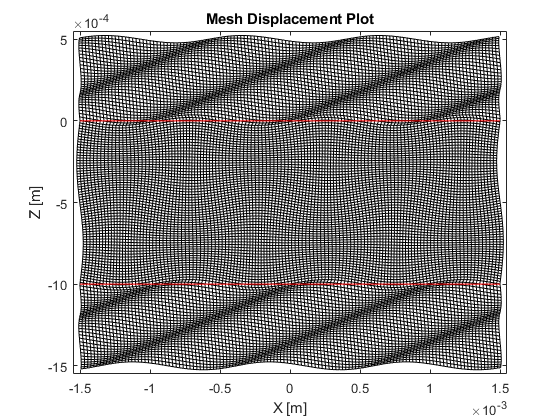


% To plot a mesh and surf plot of the displacement:
[fig_hand] = model.plotField(output_field, 'mesh', 'surf');


% To plot every style:
% [fig_hand] = model.plotField(output_field, 'all');

## Passing a Figure Handle

For some cases, like when creating a movie of the displacement field, the user may require the following figure to be plotted over the same figure axes. The` .plotField` method can take an input argument of a figure handle to prevent new figure axes being created. An example is shown here, showing the field at different time intervals on the same figure axes.

% Firstly calculate the field at t=0 s:
time = 0e-6;
[output_field] = model.calculateField(...
    plot_frequency, plot_angle, {Z, X}, time);

... calculating displacement and stress fields ...


Plot the figure with the input arguments for the plot-style, this creates two new figures where the handles are assigned to

`new_handle.mesh` and `new_handle.surf`.

new_figure_handle = model.plotField( output_field, 'mesh', 'surf');


disp(new_figure_handle)

    surf: [1×1 Figure]
    mesh: [1×1 Figure]




% Calculate the updated field at t=0.1e-6 s:
time = 0.1e-6;
[updated_field] = model.calculateField(...
    plot_frequency, plot_angle, {Z, X}, time);

... calculating displacement and stress fields ...


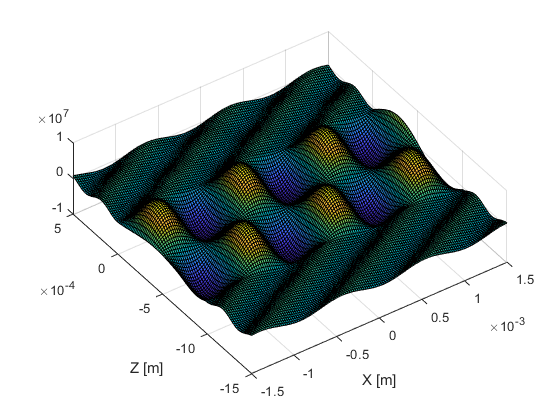

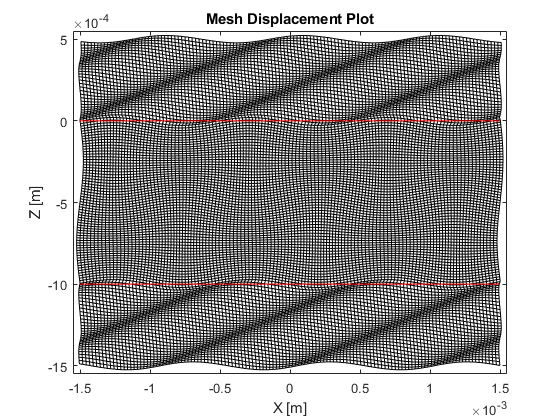


% Passing the updated_field structure and the figure handle updates the
% figures axes: 
new_figure_handle = model.plotField( updated_field, new_figure_handle);

## About

This file is part of the ElasticMatrix toolbox. Copyright (c) 2019 Danny Ramasawmy.

This file is part of ElasticMatrix. ElasticMatrix is free software: you can redistribute it and/or modify it under the terms of the GNU Lesser General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

ElasticMatrix is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU Lesser General Public License for more details.

You should have received a copy of the GNU Lesser General Public License along with ElasticMatrix. If not, see [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/).